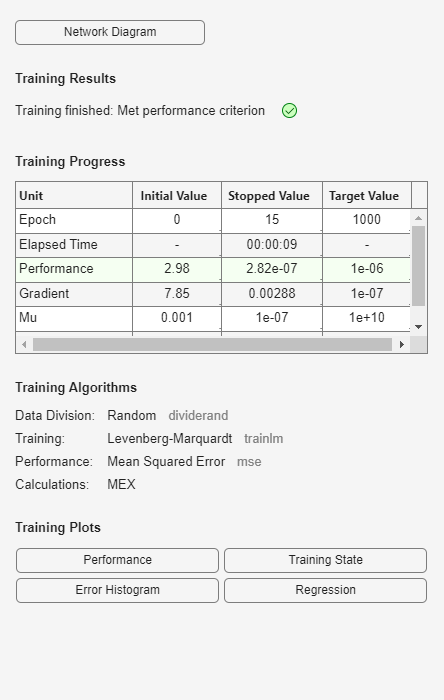

% ANN-based Droop Control
% --------------------------
% Step 1: Define Training Data
% Define input data (active and reactive power) and corresponding outputs (frequency and voltage)
X_train = [0.1, 0.2; 0.3, 0.4; 0.5, 0.6; 0.7, 0.8; 0.9, 1.0]; % Inputs: P and Q
y_train = [50, 220; 49.5, 219; 49, 218; 48.5, 217; 48, 216]; % Outputs: f and V

% Step 2: Create and Configure the Neural Network
% Initialize the neural network with 5 hidden neurons
net = feedforwardnet(5, 'trainlm');

% Configure transfer functions
net.layers{1}.transferFcn = 'tansig'; % Hidden layer uses tan-sigmoid
net.layers{2}.transferFcn = 'purelin'; % Output layer uses linear activation

% Set training parameters
net.trainParam.epochs = 1000; % Maximum number of training iterations
net.trainParam.lr = 0.01; % Learning rate
net.trainParam.goal = 1e-6; % Performance goal

% Step 3: Train the Neural Network
% Train the network with the defined inputs and outputs
[net, training_info] = train(net, X_train', y_train');

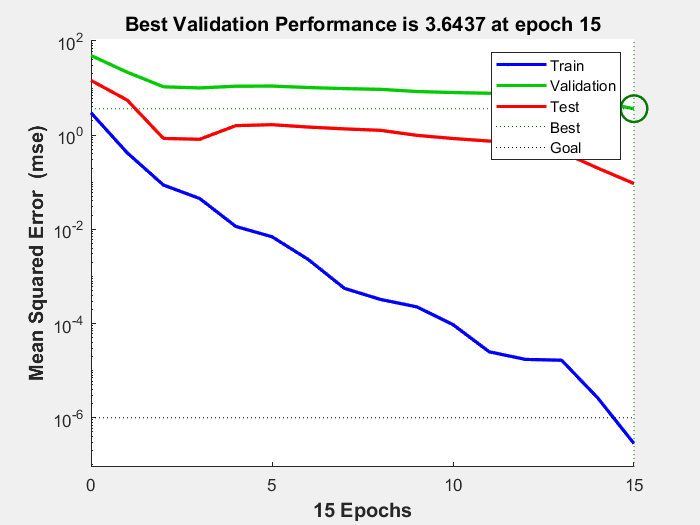


% Step 4: Visualize Training Performance
figure;
plotperform(training_info); % Plot performance vs. epochs


% Step 5: Test the Neural Network
% Define test data and predict outputs
X_test = [0.25, 0.35]';
prediction = net(X_test);
fprintf('Predicted Frequency: %.2f Hz, Predicted Voltage: %.2f V\n', prediction(1), prediction(2));

Predicted Frequency: 49.53 Hz, Predicted Voltage: 218.53 V



% Step 6: Save the Trained Network
save('trained_ann_droop.mat', 'net');

% GWO for MPPT
% --------------------------
% Step 1: Define the Objective Function
% Objective function models the PV power curve
objFunc = @(x) -((x(1) - 5)^2 + (x(2) - 3)^2); % Example quadratic objective

% Step 2: Define GWO Parameters
% Dimensions, bounds, and optimization parameters
dim = 2; % Number of variables
lb = 0; % Lower bound
ub = 10; % Upper bound
population_size = 10; % Number of wolves
max_iter = 200; % Maximum iterations

% Initialize wolf positions randomly within bounds
wolves = lb + (ub - lb) .* rand(population_size, dim);
alpha = zeros(1, dim);
beta = zeros(1, dim);
delta = zeros(1, dim);
alpha_score = inf;
beta_score = inf;
delta_score = inf;

% Step 3: Optimization Loop
for t = 1:max_iter
    % Evaluate each wolf's fitness
    for i = 1:population_size
        score = objFunc(wolves(i, :));
        % Update alpha, beta, and delta based on fitness
        if score < alpha_score
            delta_score = beta_score;
            delta = beta;
            beta_score = alpha_score;
            beta = alpha;
            alpha_score = score;
            alpha = wolves(i, :);
        elseif score < beta_score
            delta_score = beta_score;
            delta = beta;
            beta_score = score;
            beta = wolves(i, :);
        elseif score < delta_score
            delta_score = score;
            delta = wolves(i, :);
        end
    end

    % Update wolves' positions
    a = 2 - t * (2 / max_iter); % Decreasing coefficient
    for i = 1:population_size
        for j = 1:dim
            % Calculate alpha, beta, and delta influence
            r1 = rand(); r2 = rand();
            A1 = 2 * a * r1 - a;
            C1 = 2 * r2;
            D_alpha = abs(C1 * alpha(j) - wolves(i, j));
            X1 = alpha(j) - A1 * D_alpha;

            r1 = rand(); r2 = rand();
            A2 = 2 * a * r1 - a;
            C2 = 2 * r2;
            D_beta = abs(C2 * beta(j) - wolves(i, j));
            X2 = beta(j) - A2 * D_beta;

            r1 = rand(); r2 = rand();
            A3 = 2 * a * r1 - a;
            C3 = 2 * r2;
            D_delta = abs(C3 * delta(j) - wolves(i, j));
            X3 = delta(j) - A3 * D_delta;

            % Update wolf position
            wolves(i, j) = (X1 + X2 + X3) / 3;
            wolves(i, j) = max(min(wolves(i, j), ub), lb); % Bound the values
        end
    end

    % Monitor optimization progress
    if mod(t, 10) == 0
        fprintf('Iteration %d: Best Power = %.2f at [%f, %f]\n', t, -alpha_score, alpha(1), alpha(2));
    end
end

Iteration 10: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 20: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 30: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 40: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 50: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 60: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 70: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 80: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 90: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 100: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 110: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 120: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 130: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 140: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 150: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 160: Best Power = 74.00 at [0.000000, 10.000000]
Iteration 170: Best Power = 74.00 at [0.000000, 10.000000]
Iterat


% Step 4: Results
fprintf('Optimal Point: %.2f, %.2f\n', alpha(1), alpha(2));

Optimal Point: 0.00, 10.00


fprintf('Optimal Power: %.2f\n', -alpha_score);

Optimal Power: 74.00


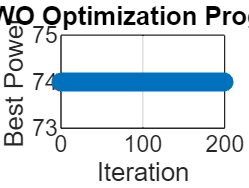


% Step 5: Visualization
figure;
plot(1:max_iter, -alpha_score * ones(max_iter, 1), '-o');
xlabel('Iteration'); ylabel('Best Power');
title('GWO Optimization Progress'); grid on;